clear;
col_tot = 1000;
row_tot = 1;
t = 1;


%% 态密度
J = 1;
delta = 0.4;
J_plus = J*(1 + delta);
J_minus = J*(1 - delta);
J_minus_x = J_minus;
J_minus_y = J_minus;
N_Lieb_site = 3;
BoundaryCond = "OBC";
Disorder = 0;
epsilon = 0 * ones(1,N_Lieb_site);


H_sparse = Lieb_2D_Hamiltonian(epsilon,J_plus,J_minus_x,J_minus_y,row_tot, col_tot, BoundaryCond);

% H_sparse = H_sparse + Disorder * sprand(speye(size(H_sparse)) - 0.5 * speye(size(H_sparse)));
tic;

%% KPM计算态密度

N_randvec = 5;
N_moments = 1000;
N_points = 2 * N_moments;
[H_tilde, a, b] = KPM_scaleHamiltonian(H_sparse);

Moments = KPM_Moments_Spectrum(H_tilde, N_randvec, N_moments,'gpu');

ans = "The computer has gpu, for matrix larger than 500 the gpu is initiated"


toc;

历时 1.519068 秒。


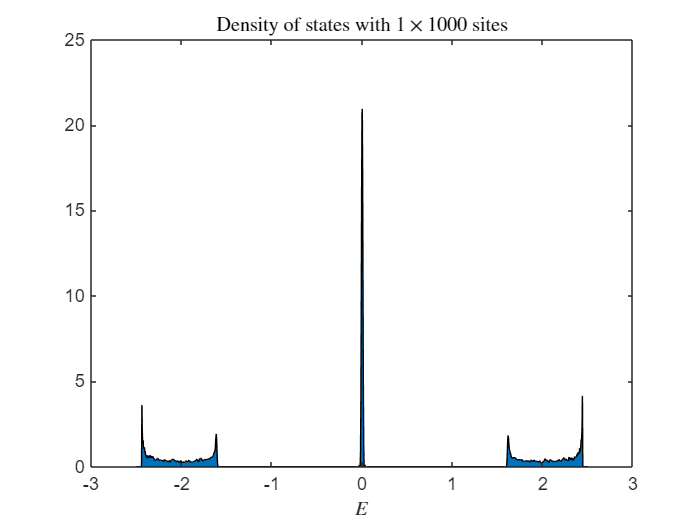

Moments_Kernel = KPM_Kernel_Correction(Moments, N_moments, 'Jackson');

[omega_dct, DOS] = KPM_DCT(Moments_Kernel, N_points);
DOS = sqrt(length(Moments_Kernel)) * DOS;
omega = KPM_rescale(omega_dct, a, b);


p = area(omega,DOS);
xlabel('$E$','Interpreter','latex')
% set(gca,'YTickLabel',[]);
title(['Density of states with ', num2str(row_tot),'$\times$', num2str(col_tot),' sites'],'interpreter','latex')

hold on

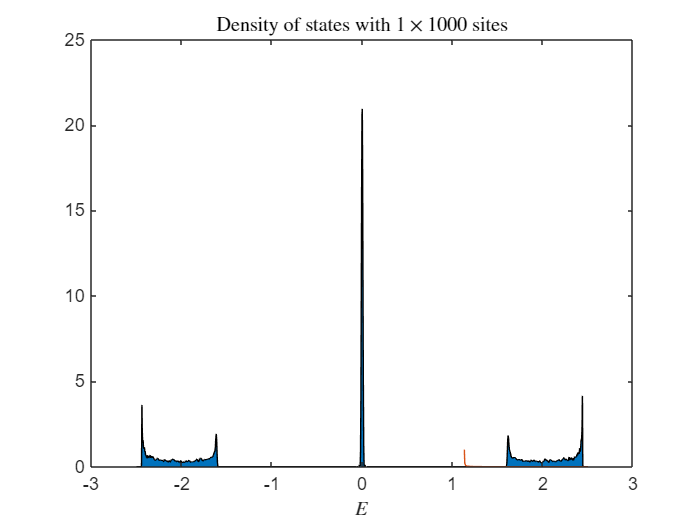


% 解析结果
omega_analy = omega(omega<2*sqrt(2)*J & omega>2*sqrt(2)*J*delta);
DOS_analytical = omega_analy./((2*(omega_analy/(2*J)).^2 *(1+delta^2) - 4*delta^2 - (omega_analy/(2*J)).^4));

plot(omega_analy, DOS_analytical/max(DOS_analytical))


function H = Lieb_2D_Hamiltonian(epsilon,J_plus,J_minus_x,J_minus_y,N_row,N_col, varargin)
%LIEB_HAMILTONIAN_REAL 给出Lieb晶格的实空间紧束缚哈密顿量
%   参数定义 Parameter definition
% epsilon: 1*3 vector, onsite energy, including chemical potential


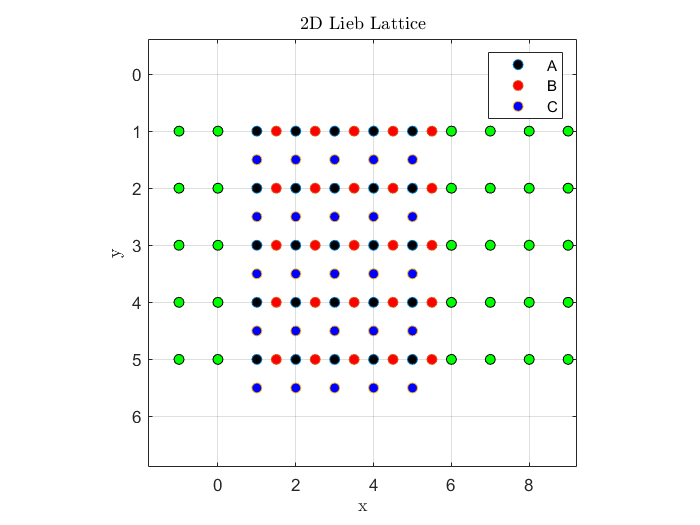

% .
% .
%% H_intra 原胞内的跃迁
% J_plus: A_n->B_n and A_n->C_n
% J_minus_x: B_xn->A_xn+1
% J_minus_y: C_yn->A_yn+1
% n: label of unit cell
    H_00 = sparse([epsilon(1), J_plus, J_plus;
        J_plus, epsilon(2),0;
        J_plus, 0, epsilon(3)]);
    %% 原胞间跃迁
    
    % 构造纵向跃迁元 Transition between row
    H01_y = sparse([0, 0, 0;
        0, 0, 0;
        J_minus_y, 0, 0]);
    H_00_OneCol = kron(speye(N_row), H_00) + kron(sparse(diag(ones(1, N_row-1),1)), H01_y) + kron(sparse(diag(ones(1, N_row-1),-1)), H01_y');
    % 当存在额外参数时，增加纵向的周期性边界条件
    if nargin > 6
        if varargin{1} == "PBC"
            if N_row > 1
                H_00_OneCol(1, end) = J_minus_y;
                H_00_OneCol(end, 1) = J_minus_y;
            end
        elseif varargin{1} == "OBC"
        else
            error("Input must be 'PBC' or 'OBC' for periodic/open boundary condition");
        end
    end
    % 构造横向跃迁元 Transition between column
    H01_x = sparse([0, J_minus_x, 0;
        0, 0, 0;
        0, 0, 0]);
    temp = tril(get_Nearest_Square_Hopping_Sparse(N_row, N_col, 0, 1));
    temp = kron(temp, H01_x);
    H_inter_x = temp + temp';
    
    
    
    H = kron(speye(N_col), H_00_OneCol) + H_inter_x;
end
